y(n) = -(1/6)y(n-1) + (1/18)y(n-2) + x(n)

1*y(n) + (1/6)y(n-1) - (1/18)y(n-2) = 1*x(n)

=> a0=1, a1=1/6, a2=-1/18, b0=1

clear;
b = 1

b = 1

a = [1 1/6 -1/18]

a =     1.0000    0.1667   -0.0556


[Hw, fw] = freqz(b, a)

Hw =    0.9000 + 0.0000i
   0.9000 + 0.0003i
   0.9000 + 0.0006i
   0.9000 + 0.0008i
   0.9000 + 0.0011i
   0.9000 + 0.0014i
   0.9000 + 0.0017i
   0.9000 + 0.0019i
   0.8999 + 0.0022i
   0.8999 + 0.0025i


fw =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


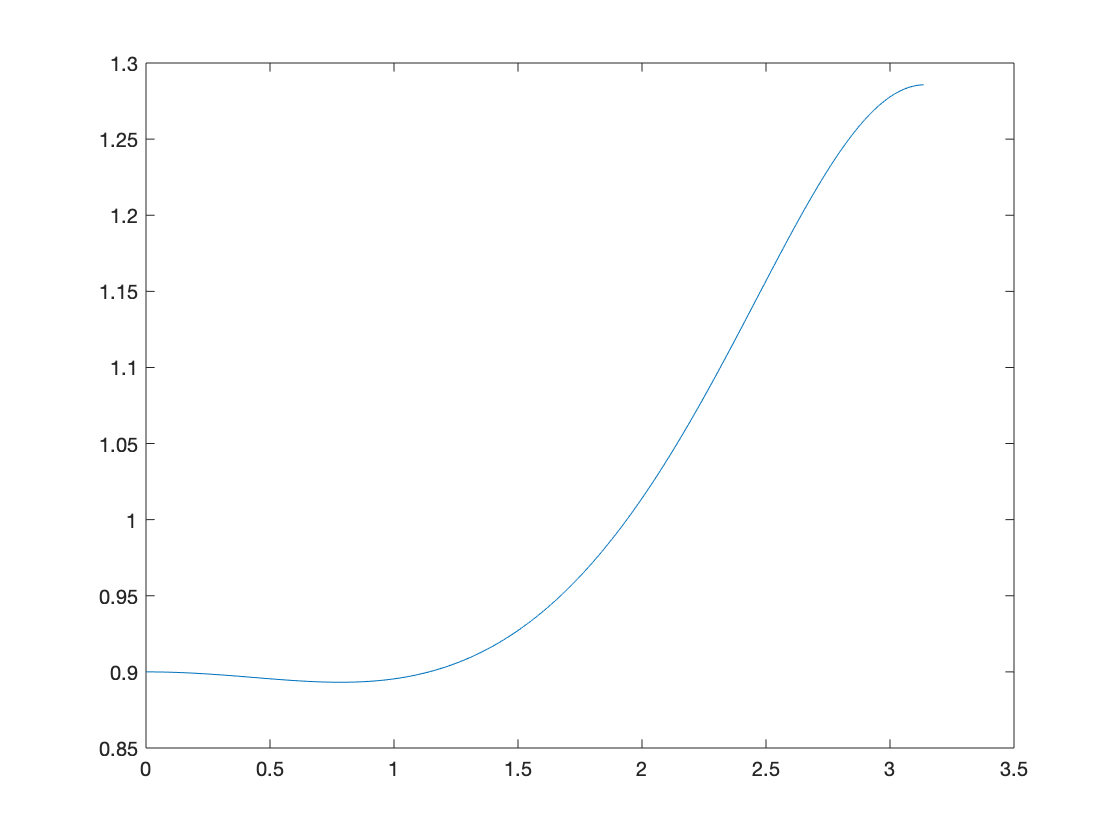

plot(fw, abs(Hw))

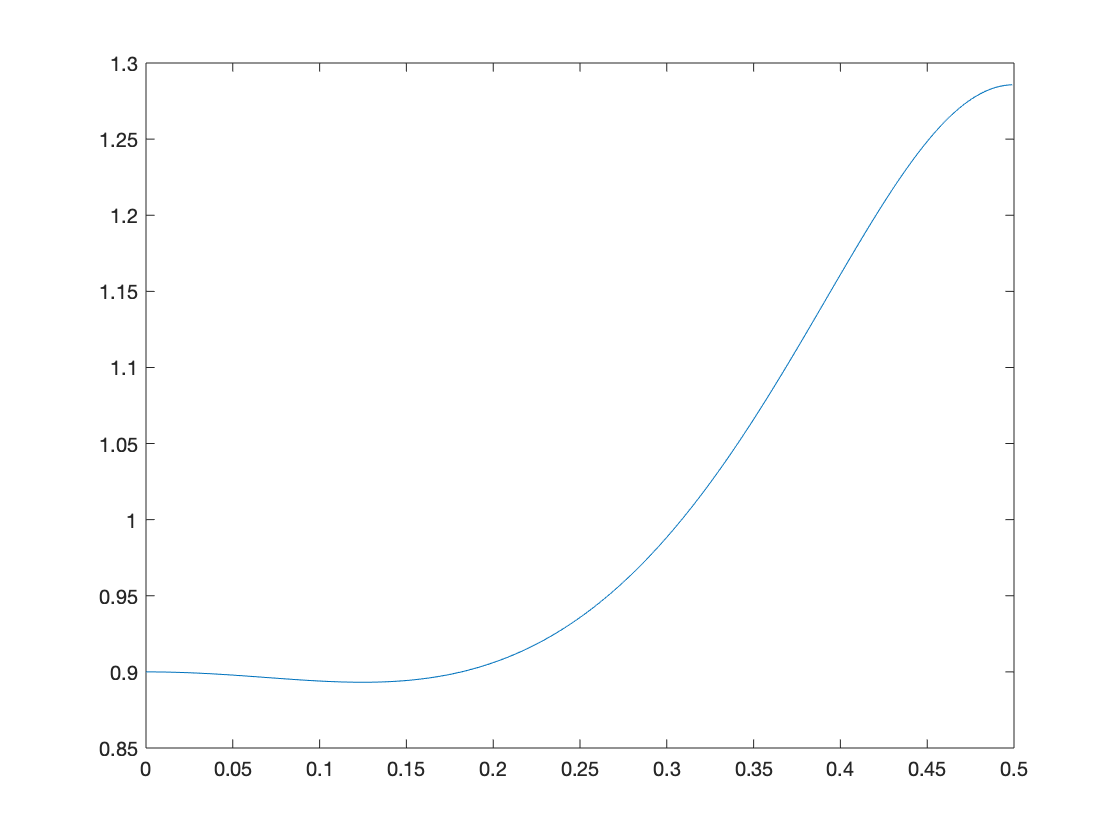

plot(fw/(2*pi), abs(Hw))

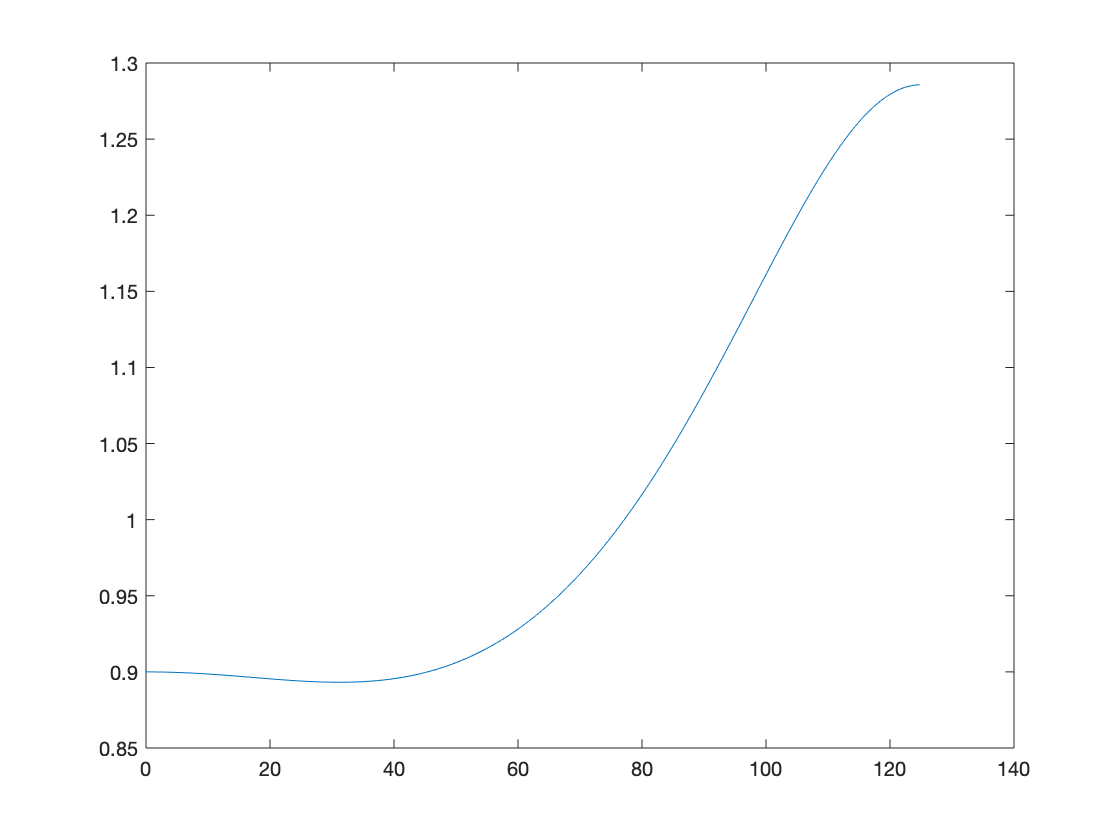

plot(fw/(2*pi)*250, abs(Hw))

Nardimo Z transformacijo

Y(z) + (1/6)*Y(z)*z^(-1) - (1/18)*Y(z)*z^(-2) = X(z)

Y(z)*(1 + (1/6)*z^(-1) - (1/18)*z^(-2)) = X(z)

H(z) = Y(z)/X(z) = 1/(1 + (1/6)*z^(-1) - (1/18)*z^(-2))

H(z) = z^2/(z^2 + (1/6)*z - (1/18)) = z^2/((z+1/3)(z-1/6))

zplane(b, a)

|H(z)| // Koda za vizualizacijo v skripti plotz

y(n-1) = x(n-1) + x(n-2) + x(n-3) + x(n-4)

y(n) = x(n) + x(n-1) + x(n-2) + x(n-3)

H(z) = 1 + z^-1 + z^-2 + z^-3

Se en primer:

y(n)= x(n) + y(n-1)-x(n-4)

y(n) - y(n-1) = x(n) -x(n-4)

Y(z)*(1-z^-1) = X(z)*(1-z^-3)

H(z) = (1-z^-4)/(1-z^-1)

H(z) = (z^4-1)/(z^4-z^3) = ((z-1)(z+1)(z-i)(z+i))/(z^3*(z-1))

b2 = [1, 1, 1, 1];
a2 = 1;
zplane(b2,a2)
b3 = [1, 0, 0, 0, -1];
a3 = [1, -1];
zplane(b3, a3)

y(n) = sum(m=0,M-1, x(n-m))

y(n) = x(n) - x(n-M) + y(n-1)

H(z) = (1-z^(-M))/(1/z^-1) => H(z) = ((1-z^-m)^M)/((1-z^-1)^M)

m = 8;
M = 1;
Nr = 1000;
Fs = 500;
f = (0:Fs/(Nr-1):Fs);

z = e^(iw) = e^(i*2*pi*(f/Fs))

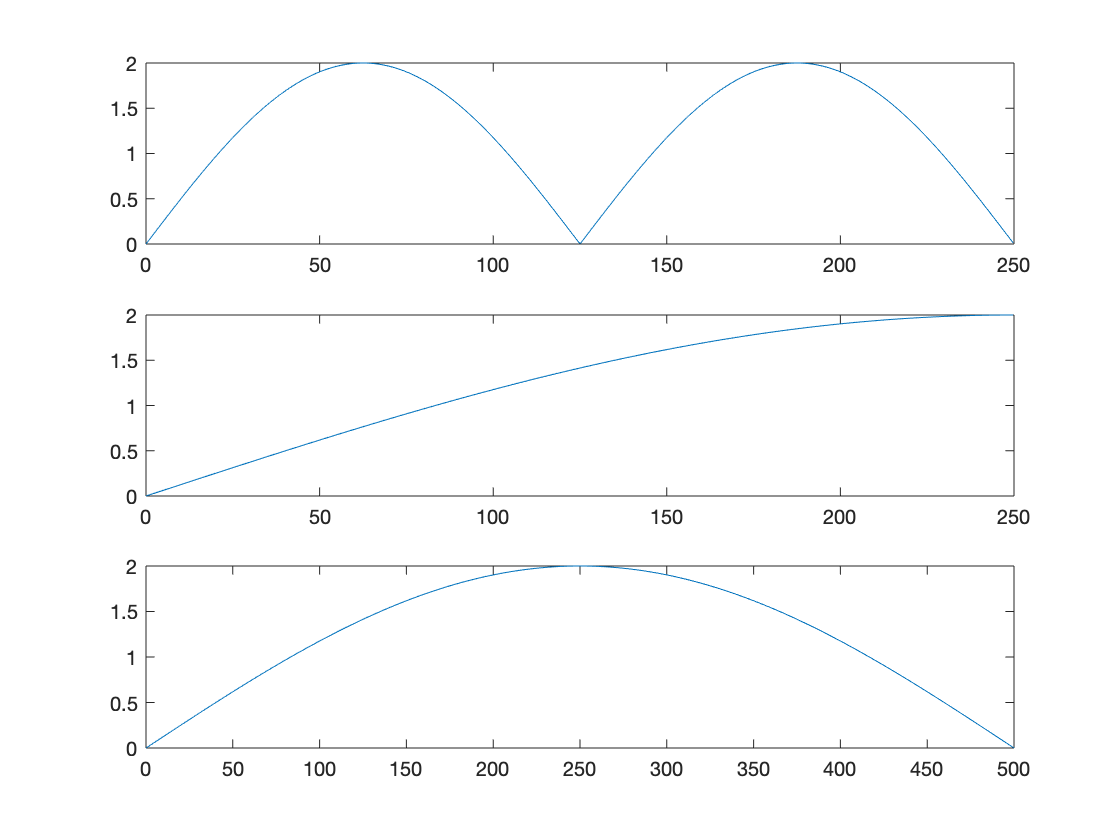

fn1 = (1-exp(-1i*2*pi*(f./Fs)*m)).^M;
fn2 = (1-exp(-1i*2*pi*(f./Fs))).^M;
plot(f, abs(fn1)); 
plot(f, abs(fn2));

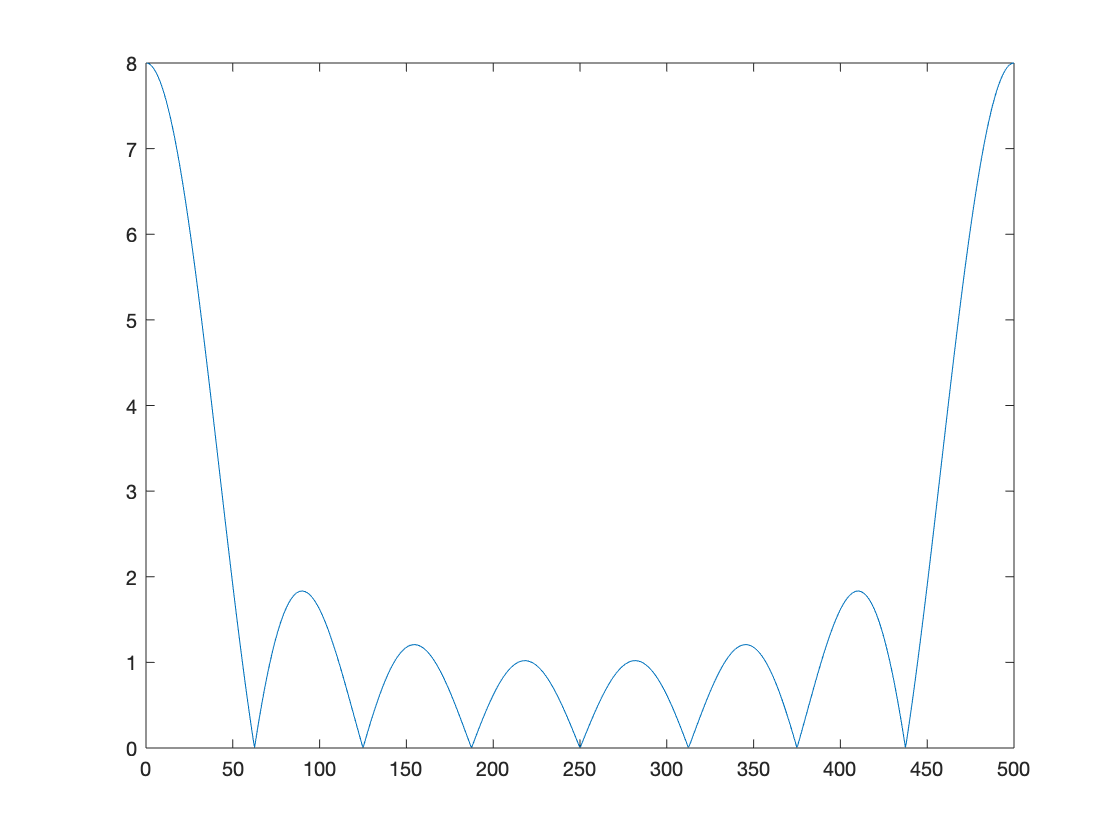

fn3 = fn1./fn2;
figure; plot(f, abs(fn3));

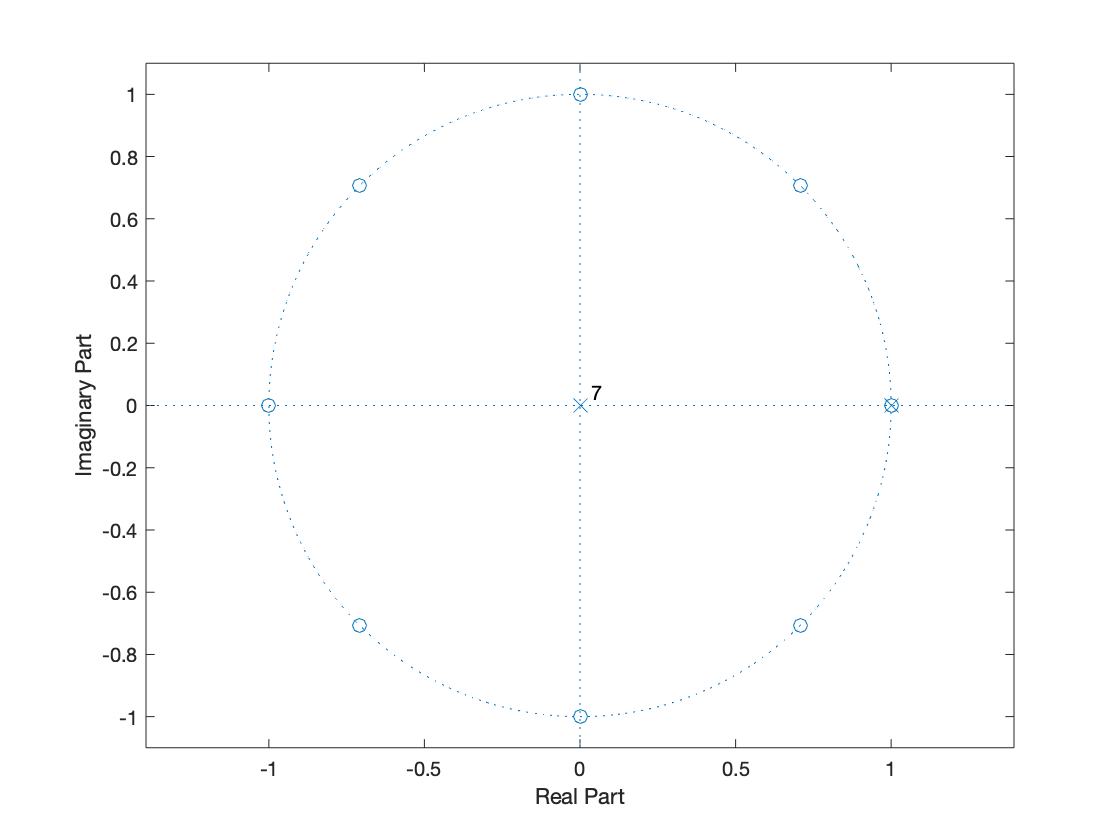

b4 = [1,0,0,0,0,0,0,0,-1];
a4 = [1,-1];
zplane(b4,a4);

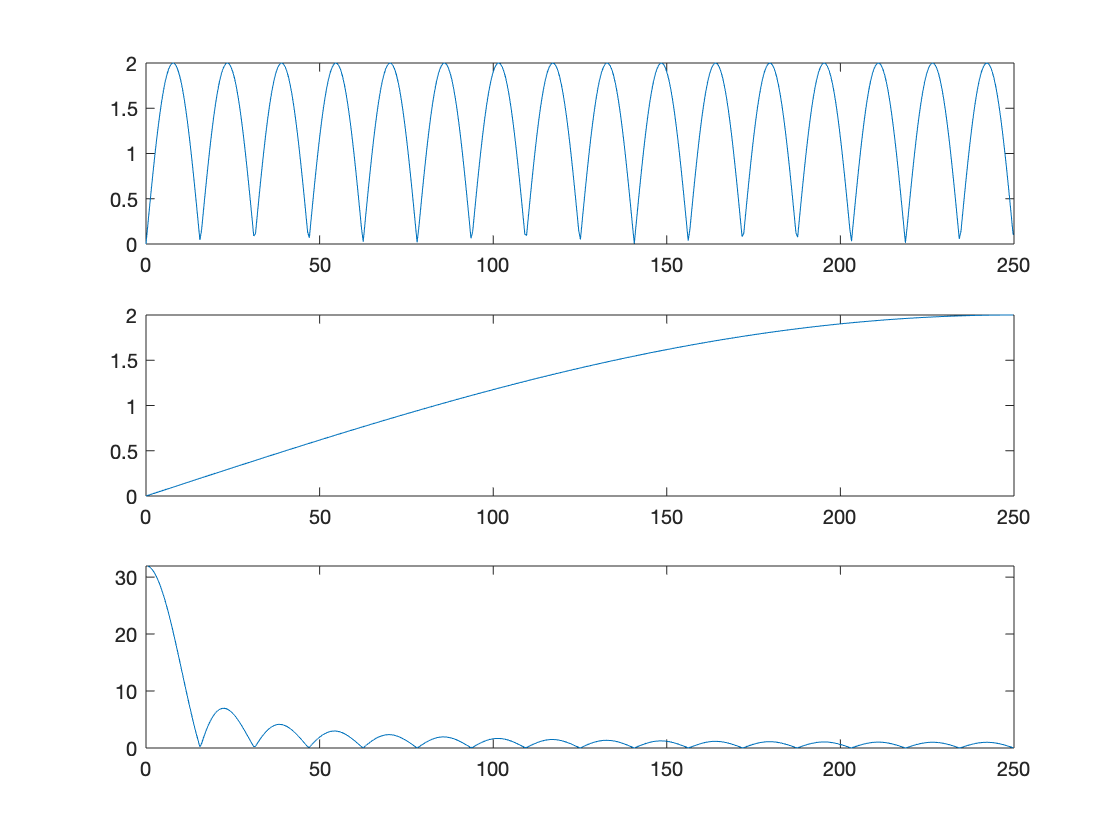

transferCharacteristic1(4, 1)
transferCharacteristic1(8, 1)
transferCharacteristic1(32, 1)

H1(z) = ((1-z^-4)^2)/((1-z^-1)^2) = ((1-z^-4)/((1-z^-1))^2 =  ((1-z^-4)/((1-z^-1))*((1-z^-4)/((1-z^-1)) = H1c(z)*H1c(z)

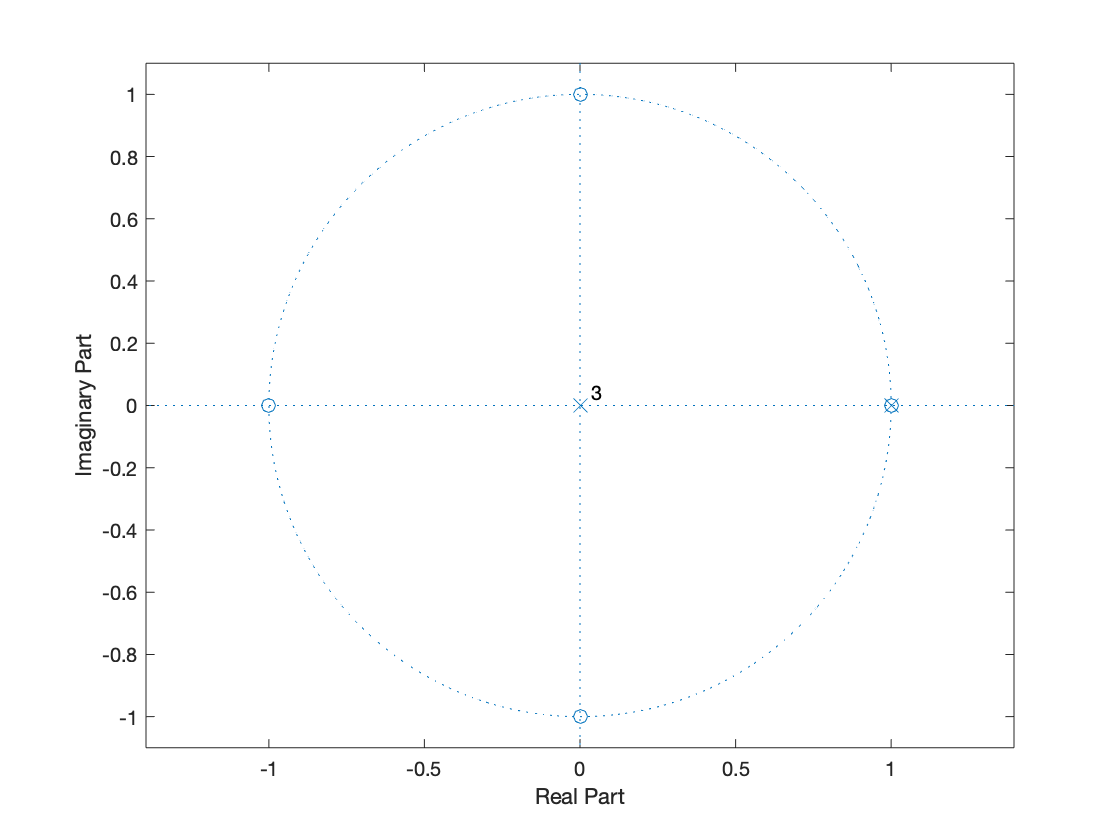

figure;
b5 = [1,0,0,0,-1];
a5 = [1,-1];
b5c = conv(b5,b5);
a5c = conv(a5,a5);
zplane(b5,a5);

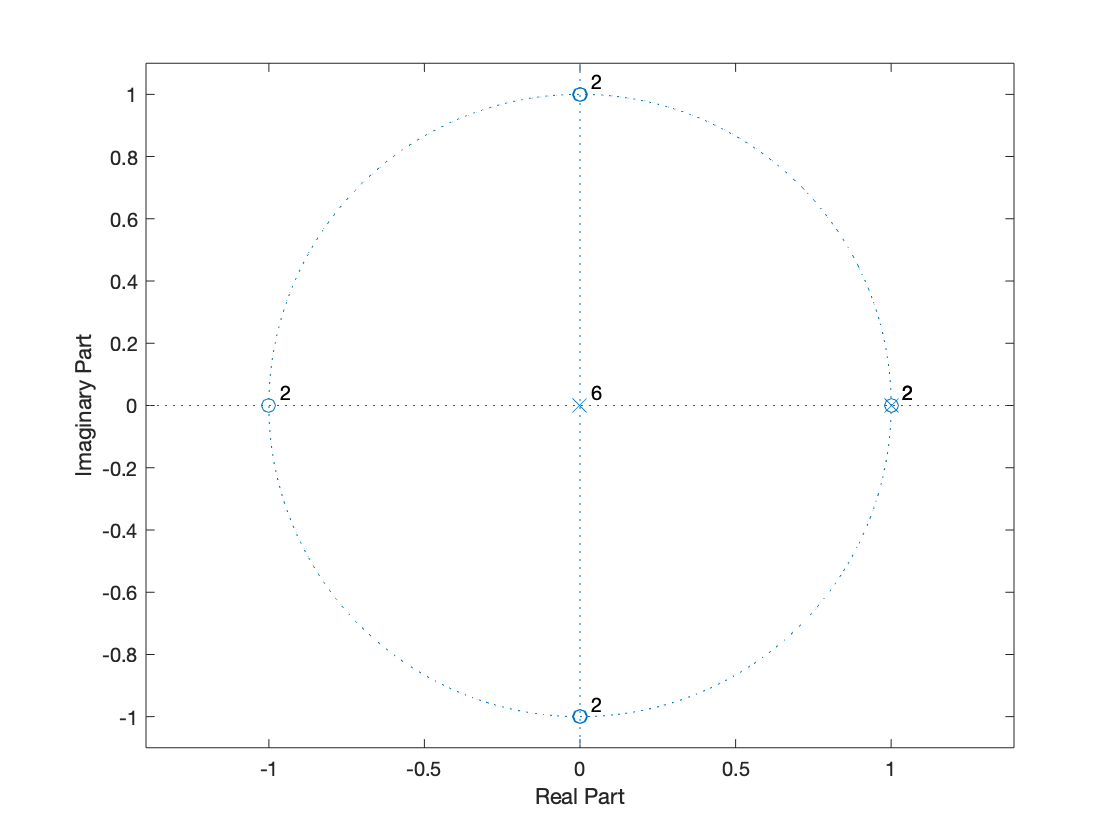

figure;
zplane(b5c,a5c);

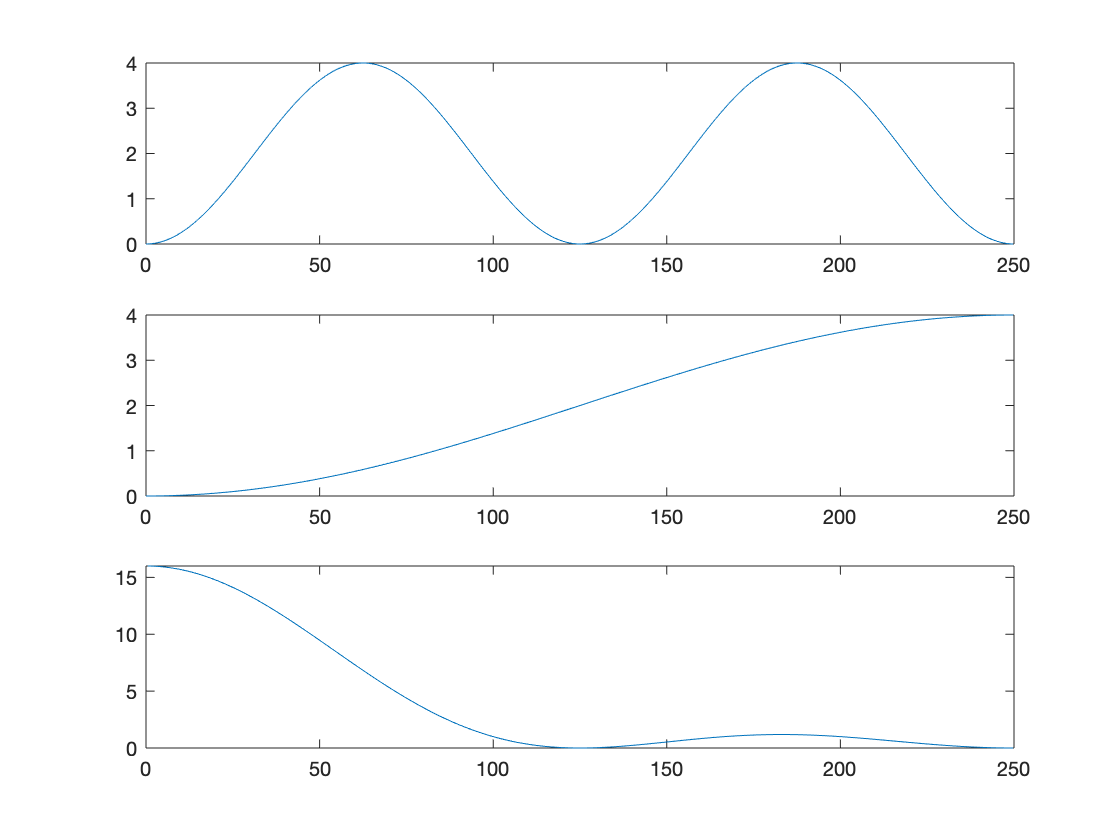

figure;
transferCharacteristic1(4,2);

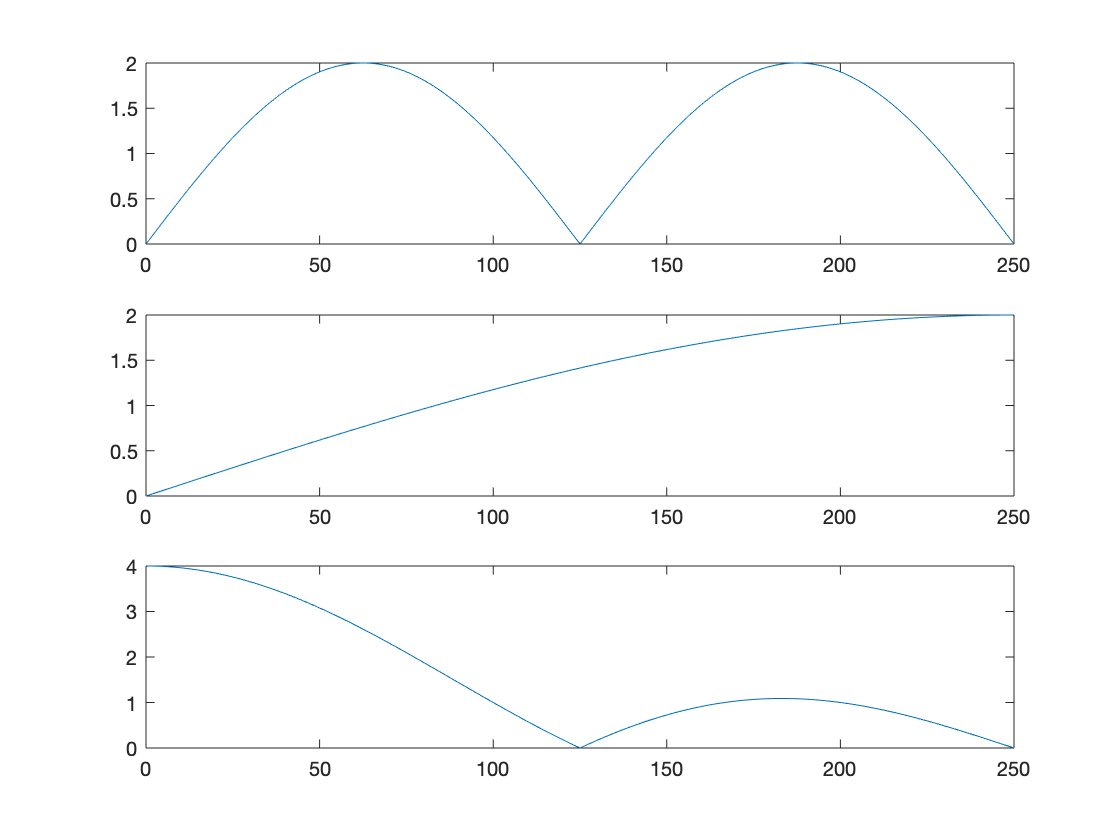

figure; transferCharacteristic1(4,1);

%[p z] = pzmap(nekej) zna bit uporaben

G1 = m^M Gain? (zacetna vrednost spodnjega grafa mejbi)

D = M*((m-1)/2) Delay?

H2(z) = (1+Ck*z^-j)^N

j=4, N=1, Ck=1 => H2 = 1+ z^-4

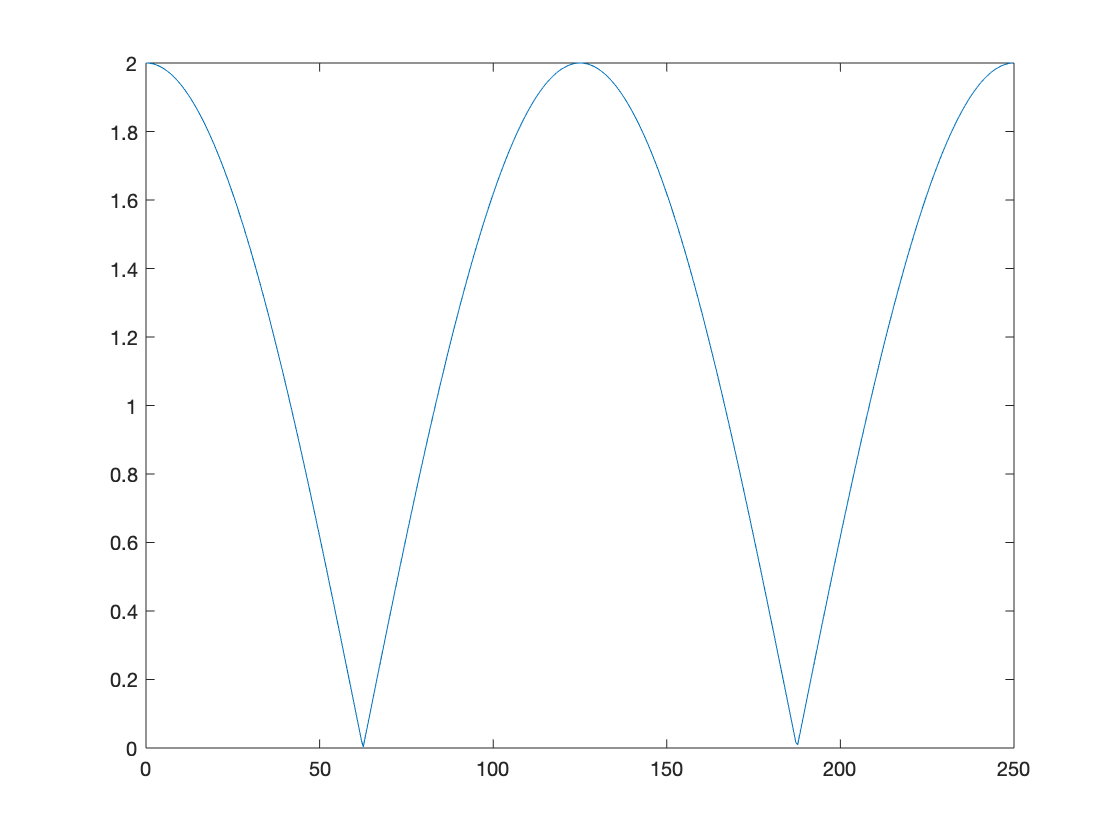

transferCharacteristic2(1,4,1);

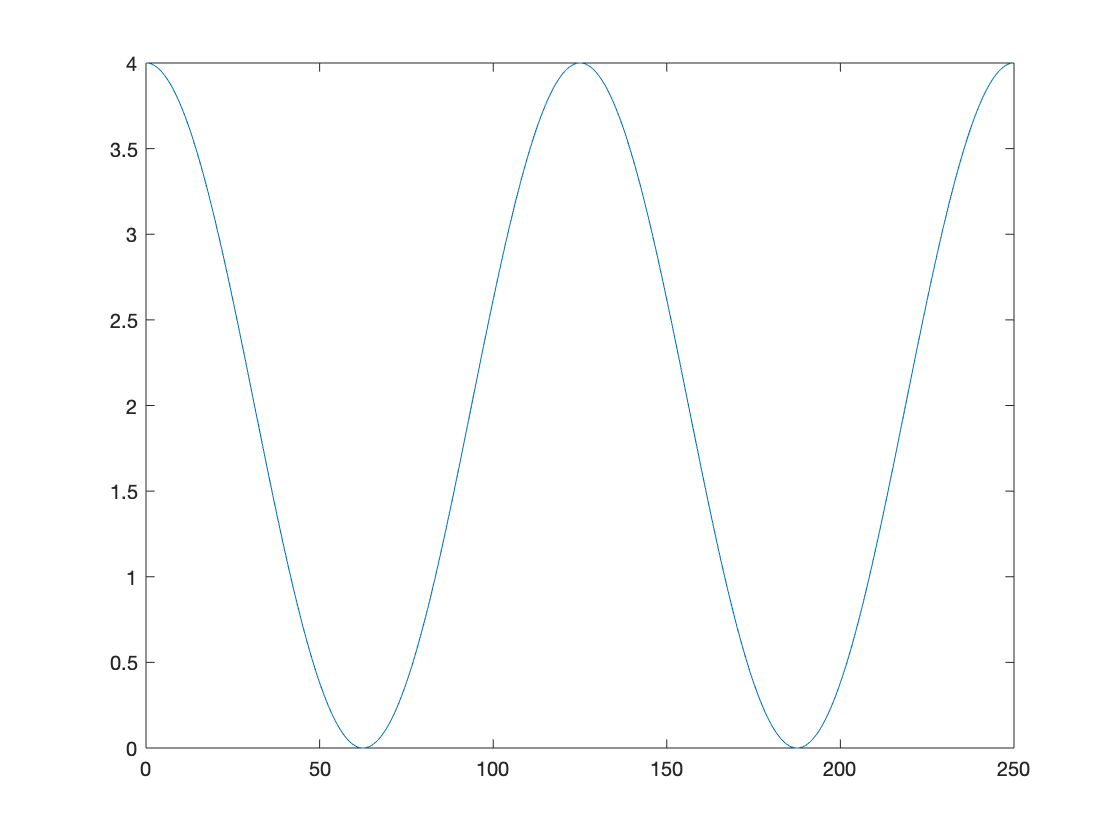

figure; transferCharacteristic2(1,4,2);

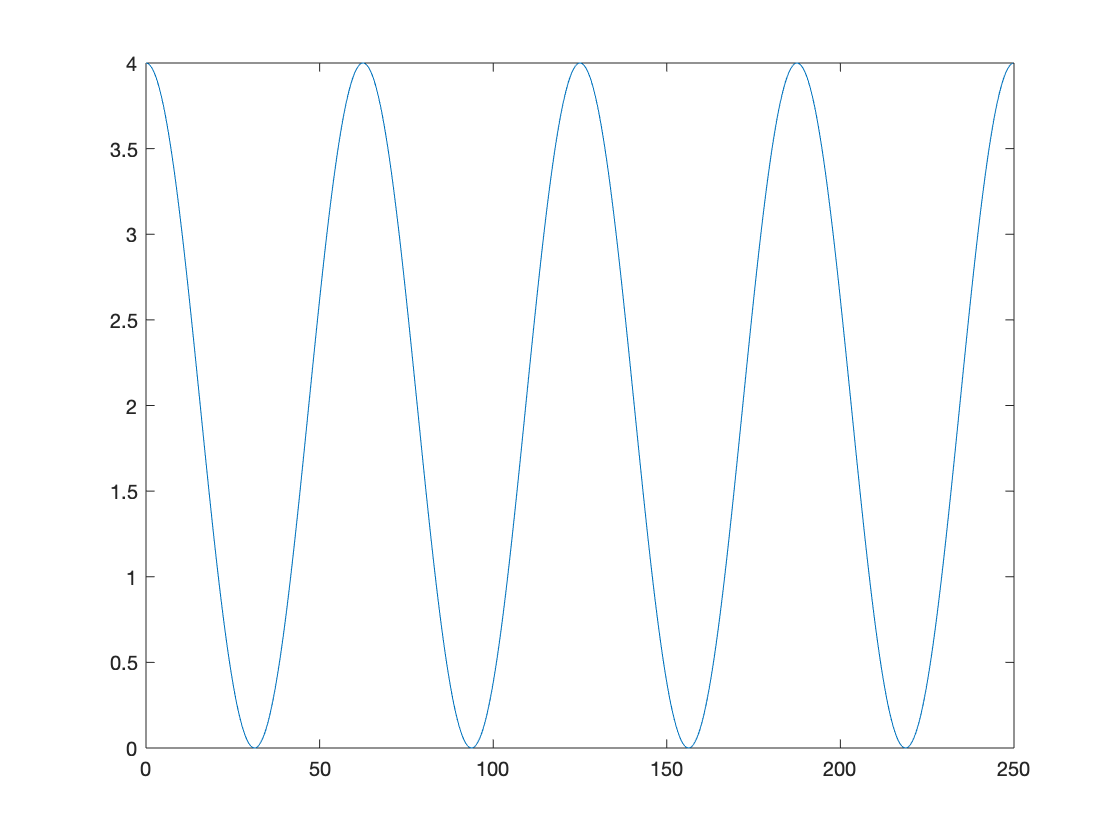

figure; transferCharacteristic2(1,8,2);

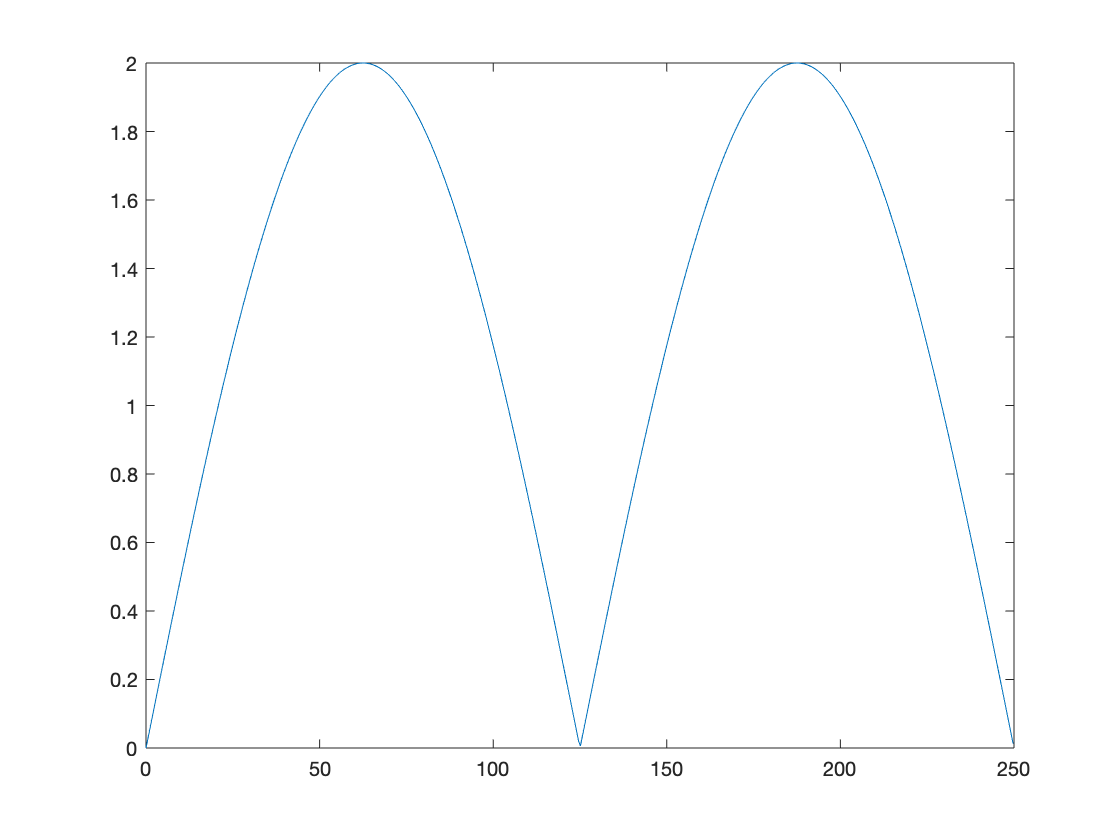

figure; transferCharacteristic2(-1,4,1);

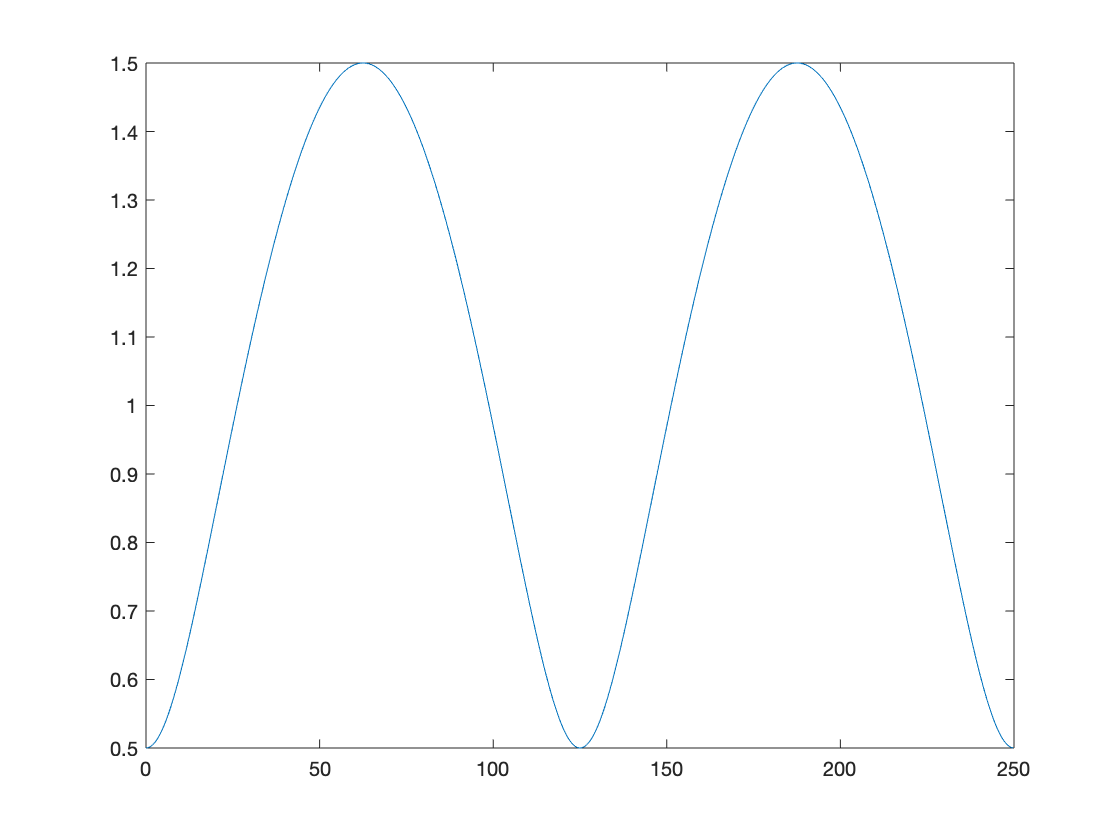

figure; transferCharacteristic2(-0.5,4,1);

H3(z) = H1(z)*H2(z)

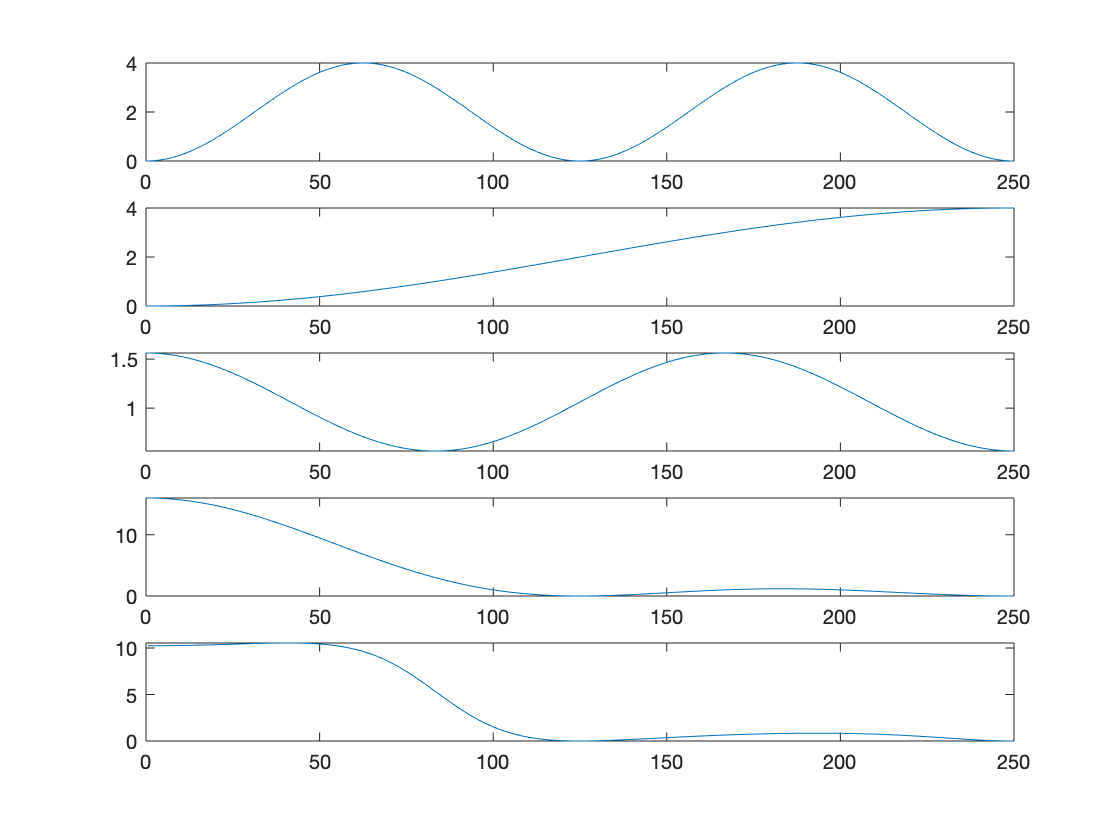

transferCharacteristic3(0.25,3,2,4,2)